format short
for H=-1:0.05:0.1
    p=[1 -(1+23/12*H) 16/12*H -5/12*H];
    r=roots(p)';
    disp([H abs(r)])
end

   -1.0000    1.7910    0.4823    0.4823
   -0.9500    1.7018    0.4823    0.4823
   -0.9000    1.6131    0.4822    0.4822
   -0.8500    1.5248    0.4819    0.4819
   -0.8000    1.4370    0.4816    0.4816
   -0.7500    1.3498    0.4812    0.4812
   -0.7000    1.2633    0.4805    0.4805
   -0.6500    1.1773    0.4796    0.4796
   -0.6000    1.0921    0.4784    0.4784
   -0.5500    1.0076    0.4769    0.4769
   -0.5000    0.9239    0.5700    0.3956
   -0.4500    0.8410    0.6174    0.3611
   -0.4000    0.7589    0.6589    0.3333
   -0.3500    0.6775    0.6984    0.3082
   -0.3000    0.5966    0.7375    0.2841
   -0.2500    0.5161    0.7773    0.2597
   -0.2000    0.8181    0.4354    0.2339
   -0.1500    0.8605    0.3535    0.2055
   -0.1000    0.9048    0.2682    0.1717
   -0.0500    0.9512    0.1734    0.1263
     0     0     0     1
    0.0500    1.0513    0.1408    0.1408
    0.1000    1.1051    0.1942    0.1942


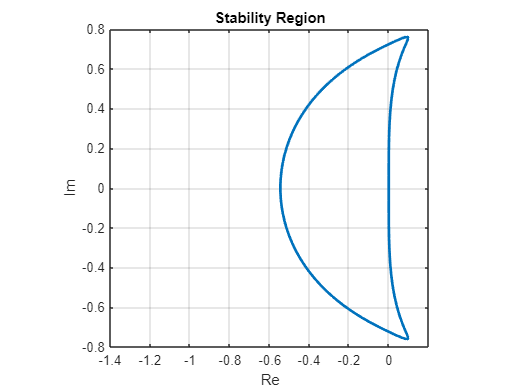

theta=linspace(0,2*pi);
xi=exp(1i*theta);
rho=xi.^3-xi.^2;
sig=(23*xi.^2-16*xi+5)/12;
z=rho./sig;

plot(z,'LineWidth',2)
axis([-1.4 0.2 -0.8 0.8])
axis('square')
grid on
xlabel('Re')
ylabel('Im')
title('Stability Region')

for H=-10:0.5:1
    p=[(1-5/12*H) -(1+8/12*H) H/12];
    r=roots(p)';
    disp([H abs(r)])
end   

  -10.0000    1.2281    0.1313
   -9.5000    1.2078    0.1322
   -9.0000    1.1858    0.1332
   -8.5000    1.1618    0.1342
   -8.0000    1.1355    0.1355
   -7.5000    1.1066    0.1369
   -7.0000    1.0747    0.1386
   -6.5000    1.0394    0.1405
   -6.0000    1.0000    0.1429
   -5.5000    0.9558    0.1457
   -5.0000    0.9059    0.1492
   -4.5000    0.8492    0.1536
   -4.0000    0.7844    0.1594
   -3.5000    0.7096    0.1672
   -3.0000    0.6228    0.1784
   -2.5000    0.5220    0.1955
   -2.0000    0.4058    0.2240
   -1.5000    0.2774    0.2774
   -1.0000    0.3872    0.1519
   -0.5000    0.6084    0.0567
     0     0     1
    0.5000    1.6524    0.0319
    1.0000    2.8062    0.0509


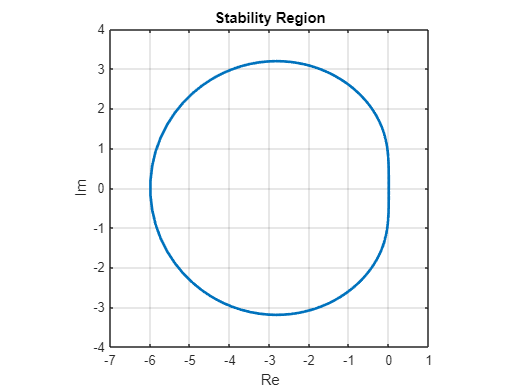

theta=linspace(0,2*pi,200);
xi=exp(1i*theta);
rho=xi.^2-xi;
sig=(5*xi.^2+8*xi-1)/12;
z=rho./sig;

plot(z,'LineWidth',2)
axis([-7 1 -4 4])
axis('square')
grid on
xlabel('Re')
ylabel('Im')
title('Stability Region')